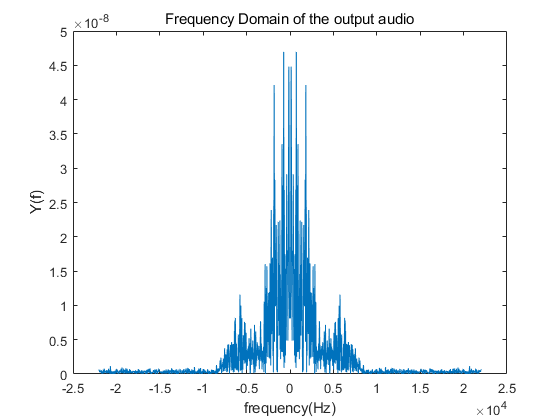

clc;clear;close all;clear sound;

fs=44100;
time=30; % 30 seconds
head=1;
framesize=1024;
deviceReader = audioDeviceReader("SampleRate",fs);
setup(deviceReader);                     % initialize
deviceWriter = audioDeviceWriter("SampleRate",fs);
setup(deviceWriter,zeros(framesize,2));  % initialize
aud=zeros(fs*time,1); % audio container
tic
while toc < time
    frame=deviceReader();
    aud(head:head+framesize-1)=frame;
    deviceWriter(frame);
end

N=fs*time;
Y=fftshift(fft(aud))/N;
f=(-N/2:N/2-1)*fs/N;
plot(f,abs(Y));
%axis([-2500 2500 0 inf]);
title("Frequency Domain of the output audio");
xlabel("frequency(Hz)");
ylabel("Y(f)")